# Example 2: Generation of velocity histories

 In the example 2, a higher sampling frequency is used with only 49 nodes. The point is to compare the simulated and target power spectral densities (PSDs)

## Set sampling frequency and record duration

clearvars;close all;clc;

fs = 9; % sampling frequency (in Hertz)
M = 15; % M is the power of 2: If M = 10, 2^M = 1024 time step
[t,f] = getSamplingPara(M,fs);

Duration of target time series is 1.01 hours, i.e. 3.64e+03 sec 



N=numel(t); % number of time step (should be equal to 2^M)
Nfreq = numel(f); % number of frequency step (should be equal to 2^(M-1))
dt = median(diff(t)); % time step (should be equal to 1/fs)



## Set the geometry (a simple grid)

Nyy = 7; % number of nodes along the y axis
Nzz = 7; % number of nodes along the z axis

ymin = -75;
ymax = 75;

zmax = 30 ;
zmin= 30+150;

y = linspace(ymin,ymax,Nyy);
z = linspace(zmin,zmax,Nzz);

[Y,Z] = meshgrid(y,z);

## Visualization of the grid

The dots show where the velocity fluctuations are going to be generated

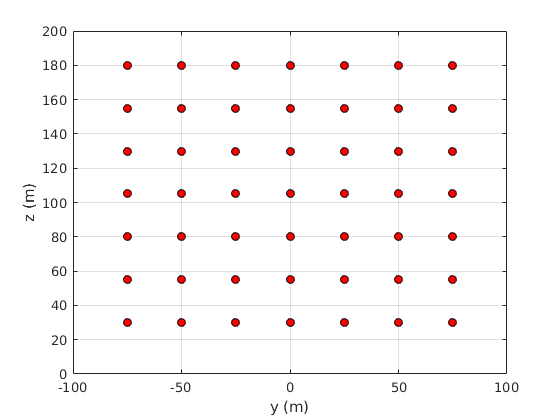

clf;close all
figure
axis equal
plot(Y(:),Z(:),'ko','markerfacecolor','r')
xlabel('y (m)')
ylabel('z (m)')
xlim([-100,100])
ylim([0 200])
grid on

set(gcf,'color','w')

## Set the target mean wind velocity

u_star = 0.8; % Friction velocity (m/s);
kappa = 0.4; % von karman constant
z0 = 0.03; % roughness length;
U = u_star/kappa.*log(Z./z0);


## Set the target wind coherence parameters

The davenport model is used for the sake of simplicity

CohDecay.Cuy = 7; % Arbitrary decay coefficient for u in the "y" direction
CohDecay.Cuz = 10; % Arbitrary decay coefficient for u in the "z" direction
CohDecay.Cvy = 7; % Arbitrary decay coefficient for v in the "y" direction
CohDecay.Cvz = 10; % Arbitrary decay coefficient for v in the "z" direction
CohDecay.Cwy = 6.5; % Arbitrary decay coefficient for w in the "y" direction
CohDecay.Cwz = 3; % Arbitrary decay coefficient for w in the "z" direction


## Set the wind spectral density at each nodes

Su, Sv, Sw and Suw are not normalized here! They are expressed as [Nm x N] matrices where Nm = Nz x Ny.

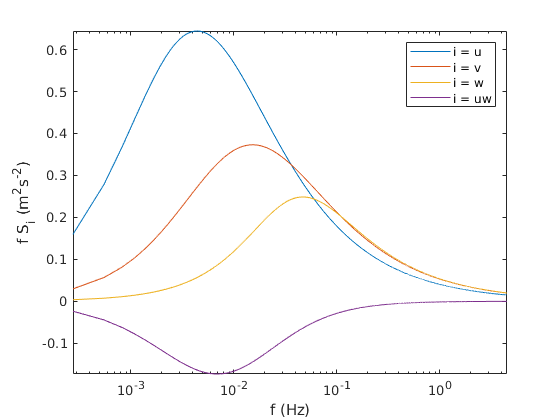

[Su,Sv,Sw,Suw,~] = KaimalModel(U,Z,f,u_star);

figure
semilogx(f,f.*Su(1,:),f,f.*Sv(1,:),f,f.*Sw(1,:),f,f.*Suw(1,:))
axis tight
ylabel('f S_i (m^2s^{-2})')
xlabel('f (Hz)')
legend('i = u','i = v','i = w','i = uw')

set(gcf,'color','w')

## Run the function windSimFast

The PSDs of the velocity are calculated outside the function windSimFast, whereas the coherence is calculated inside the function windSimFast to keep a balance between robustness and code performance. 


tic
[u,v,w,nodes] = windSimFast(U,f,Su,Sv,Sw,CohDecay,Y,Z,'Suw',Suw); %  Suw is here an option!

Expected computation time: From 52 to 109 seconds 


toc

Elapsed time is 16.841170 seconds.



u = bsxfun(@plus,u,U(:)');
u = reshape(u,N,Nzz,Nyy); % whos u1
v = reshape(v,N,Nzz,Nyy); % whos u1
w = reshape(w,N,Nzz,Nyy);% whos w1



## Time series overview

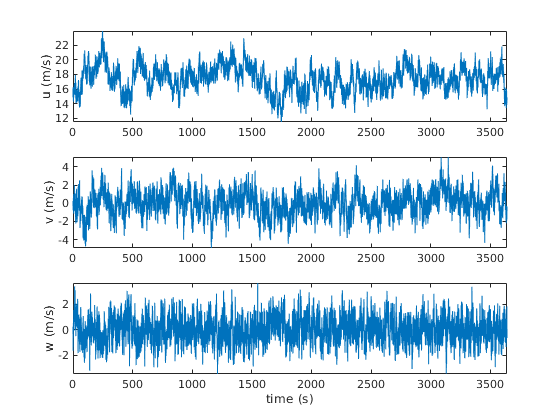

clf;close all;
figure
subplot(311)
plot(t,squeeze(u(:,1,1)))
ylabel('u (m/s)')
axis tight
subplot(312)
plot(t,squeeze(v(:,1,1)))

ylabel('v (m/s)')
axis tight
subplot(313)
plot(t,squeeze(w(:,1,1)))
xlabel('time (s)')
ylabel('w (m/s)')
axis tight

set(gcf,'color','w')

## Mean profile of the wind speed

THis is simply done to check that the matrix u, v and w have been properly reshaped from 2D to 3D matrices

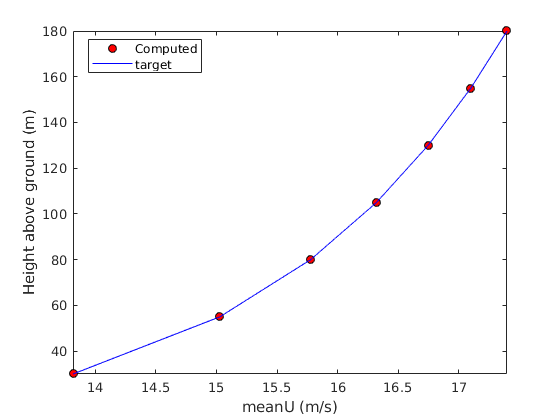

clf;close all;
figure

plot(squeeze(mean(u(:,:,1))),z,'ko','markerfacecolor','r')
hold on
plot(U(:,1),z,'b')
legend('Computed','target','location','best')
xlabel('meanU (m/s)')
ylabel('Height above ground (m)')
axis tight

set(gcf,'color','w')

## PSD estimates and comparison with target spectrum (kaimal model)

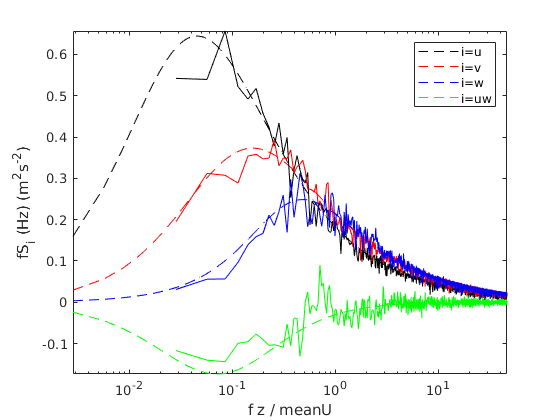


Nf = round(N/10); % numbe of points for each segments (50% overlapping)
[Su0,f0]=pmtm(detrend(squeeze(u(:,1,1))),4,Nf,fs);
[Sv0,~]=pmtm(squeeze(v(:,1,1)),4,Nf,fs);
[Sw0,~]=pmtm(squeeze(w(:,1,1)),4,Nf,fs);
[Suw0,~]=cpsd(detrend(squeeze(u(:,1,1))),detrend(w(:,1,1)),Nf,round(Nf/2),Nf,fs);

Su0 = f0.*Su0;
Sv0 = f0.*Sv0;
Sw0 = f0.*Sw0;
Suw0 = f0.*real(Suw0);

fr0 = Z(1,1)./U(1,1).*f0;

fr = Z(1,1)./U(1,1).*f;

clf;close all;
figure
semilogx(fr,f.*Su(1,:),'k--',fr,f.*Sv(1,:),'r--',fr,f.*Sw(1,:),'b--',fr,f.*Suw(1,:),'g--')
hold on; box on;
semilogx(fr0,Su0,'k',fr0,Sv0,'r',fr0,Sw0,'b',fr0,Suw0,'g')
% hold on
% plot([1 10],0.3*[1 10].^(-2/3),'m')
xlabel('f z / meanU')
ylabel('fS_i (Hz) (m^2s^{-2})')
axis tight
set(gcf,'color','w')
legend('i=u','i=v','i=w','i=uw')

## Co-Coherence estimation (vertical separations)

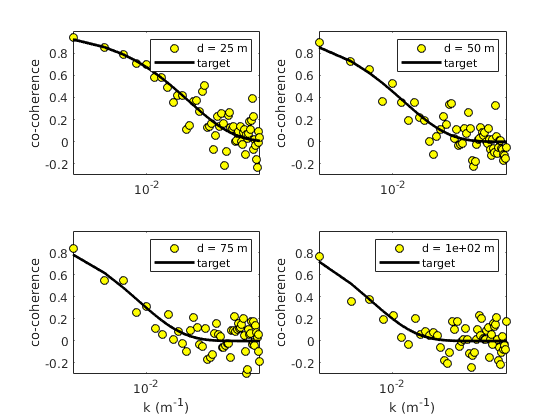

Nblock = 20; % a lot of block here to make it easier to visualize
Ncoh = round(N/Nblock);
if mod(Ncoh,2)
    cocoh = zeros(Nzz,Nzz,round(Ncoh/2));
else
    cocoh = zeros(Nzz,Nzz,round(Ncoh/2)+1);
end
% computation of the cocoherence using the function coherence
for ii=1:Nzz
    for jj=1:Nzz
        [cocoh(ii,jj,:),~,freq] = coherence(u(:,jj,1),u(:,ii,1),Ncoh,round(Ncoh/2),Ncoh,fs);
    end
end
% matrix distance along y
dz = abs(z(:)-z(:)');
uCoh = 0.5* abs(U(:,1)+U(:,1)'); % average between two heights


distTarget = [25,50,75,100];
figure
for ii=1:numel(distTarget)
    [~,indDist] = min(abs(dz(1,:)-distTarget(ii)));
    k = 2*pi*freq./uCoh(1,ii);
    subplot(2,2,ii)
    semilogx(k,squeeze(cocoh(1,indDist,:)),'ko','markerfacecolor','y');
    box on;hold on
    plot(k,exp(-CohDecay.Cuz.*dz(1,indDist).*freq/uCoh(1,ii)),'k','linewidth',2);
    legend(['d = ',num2str(dz(1,indDist),2),' m'],'target');
    xlim([0,0.12])
    ylim([-0.3,1])
    ylabel('co-coherence')
    if ii>2,        xlabel('k (m^{-1})');    end
    set(gcf,'color','w')
end